% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 23);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "datetime", "categorical", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "Timezone", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");

% Import the data
StormEvents_2018 = readtable("C:\Users\froooti\OneDrive\Desktop\MATLAB\StormEvents\StormEvents\StormEvents_2018.csv", opts);

% Clear temporary variables
clear opts

% Display results
StormEvents_2018

StormEvents_2018 = 61742×23 table
    EpisodeID      Event_ID      State      Year      Month         Event_Type          Begin_Date_Time       Timezone       End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                      

%Extract data for only Hurricane
StormEvents_2018 = StormEvents_2018(StormEvents_2018.Event_Type == 'Hurricane',:)

StormEvents_2018 = 60×23 table
    EpisodeID      Event_ID         State         Year      Month      Event_Type      Begin_Date_Time       Timezone       End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                          

events = readtable("C:\Users\froooti\OneDrive\Desktop\MATLAB\StormEvents\StormEvents\StormEvents_2018.csv");

% Set missing Property and Crop Cost to $0
events.Property_Cost(ismissing(events.Property_Cost)) = 0;
events.Crop_Cost(ismissing(events.Crop_Cost)) = 0;

% Add total damage to the table
events.Total_Damage = events.Property_Cost+ events.Crop_Cost

events = 61742×24 table
    EpisodeID      Event_ID        State        Year        Month             Event_Type            Begin_Date_Time       Timezone        End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                   

% Code to know the two most affected states

events = events(strcmp(events.Event_Type,'Hurricane'),:);
events = events(~ismissing(events.Total_Damage),:);
events = sortrows(events, "Total_Damage", "descend")

events = 60×24 table
    EpisodeID      Event_ID           State           Year        Month         Event_Type        Begin_Date_Time       Timezone        End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                        

%considering the Total damage column, it is concluded that The state of
%North Carolina and Georgia are the most affected states.
%Get the table
events.Total_Damage = events.Property_Cost+ events.Crop_Cost

events = 60×24 table
    EpisodeID      Event_ID           State           Year        Month         Event_Type        Begin_Date_Time       Timezone        End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                        

% show the most affected top two states
events = events(ismember(events.State,{'GEORGIA','NORTH CAROLINA'}),:)

events = 31×24 table
    EpisodeID      Event_ID           State           Year        Month         Event_Type        Begin_Date_Time       Timezone        End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                        

% code to display only the events that include only the two most affected states
StormEvents_2018 = StormEvents_2018(ismember(StormEvents_2018.State,{'GEORGIA','NORTH CAROLINA'}),:)

StormEvents_2018 = 31×23 table
    EpisodeID      Event_ID         State         Year      Month      Event_Type      Begin_Date_Time       Timezone       End_Date_Time        Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                                          

stat = "sum";
Hurricane = events(events.Event_Type == "Hurricane",:);
cost = groupsummary(Hurricane, "Month", stat,"Total_Damage" )

cost = 2×3 table
        Month        GroupCount    sum_Total_Damage
    _____________    __________    ________________

    {'October'  }        22           4.4042e+09   
    {'September'}         9           1.4655e+09   


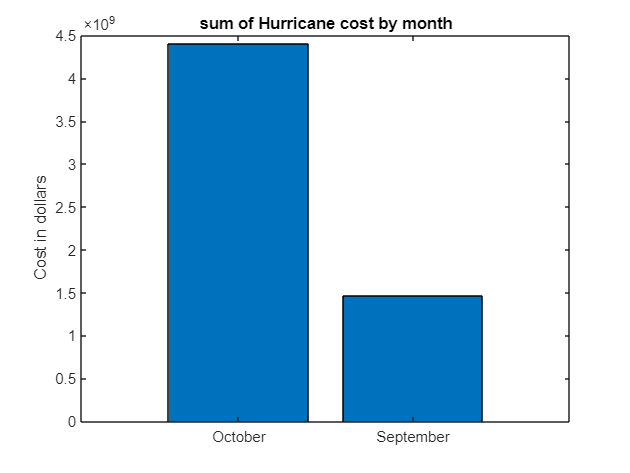

% View the results using a bar chart
bar(cost.Month, cost{:, end})
title(stat + " of Hurricane cost by month")
ylabel("Cost in dollars")

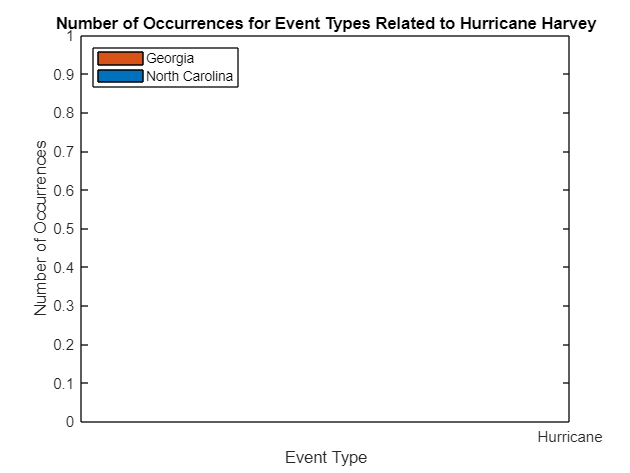

% Filter data for events related to Hurricane Harvey in North Carolina and Georgia
nc_events_harvey = events(strcmp(events.State, 'North Carolina') & events.Event_Type == "Hurricane", :);
ga_events_harvey = events(strcmp(events.State, 'Georgia') & events.Event_Type == "Hurricane", :);

% Count the occurrences of each event type in North Carolina and Georgia
nc_event_counts = countcats(categorical(nc_events_harvey.Event_Type));
ga_event_counts = countcats(categorical(ga_events_harvey.Event_Type));

% List of event types
event_types = categories(categorical(events.Event_Type));

% Plotting
figure;
bar([nc_event_counts, ga_event_counts], 'stacked');
xticks(1:length(event_types));
xticklabels(event_types);
xlabel('Event Type');
ylabel('Number of Occurrences');
title('Number of Occurrences for Event Types Related to Hurricane Harvey');
legend('North Carolina', 'Georgia', 'Location', 'northwest');

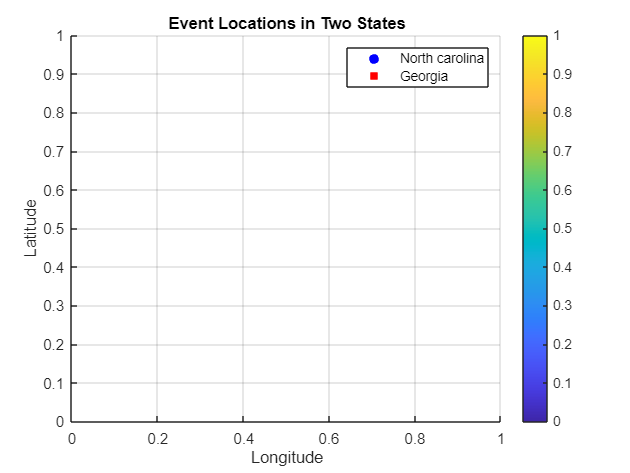

% Filter data for the two states
state1_events = events(strcmp(events.State, 'North Carolina'), :);
state2_events = events(strcmp(events.State, 'Georgia'), :);

% Plot event locations on a map
figure;
hold on;

% Plot events for State 1
scatter(state1_events.Begin_Lon, state1_events.Begin_Lat, 'filled', 'Marker', 'o', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');

% Plot events for State 2
scatter(state2_events.Begin_Lon, state2_events.Begin_Lat, 'filled', 'Marker', 's', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');

% Customize plot
xlabel('Longitude');
ylabel('Latitude');
title('Event Locations in Two States');
legend('North carolina', 'Georgia');
grid on;

hold off;

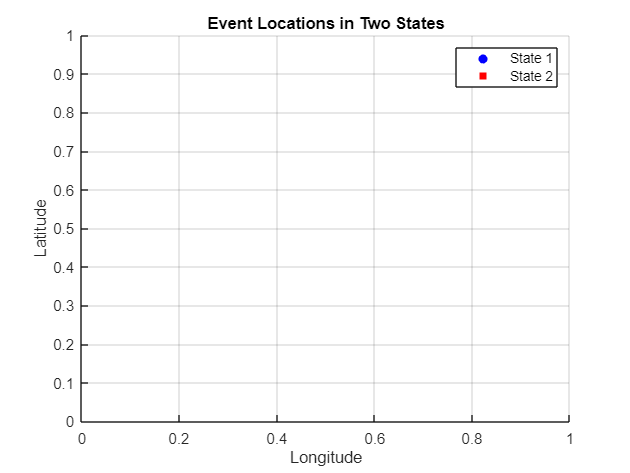

% Filter data for the two states
state1_events = events(strcmp(events.State, 'State1'), :);
state2_events = events(strcmp(events.State, 'State2'), :);

% Plot event locations on a map
figure;
hold on;

% Plot events for State 1
scatter(state1_events.Begin_Lon, state1_events.Begin_Lat, 100, 'b', 'filled', 'o');

% Plot events for State 2
scatter(state2_events.Begin_Lon, state2_events.Begin_Lat, 100, 'r', 'filled', 's');

% Customize plot
xlabel('Longitude');
ylabel('Latitude');
title('Event Locations in Two States');
legend('State 1', 'State 2');
grid on;

hold off;

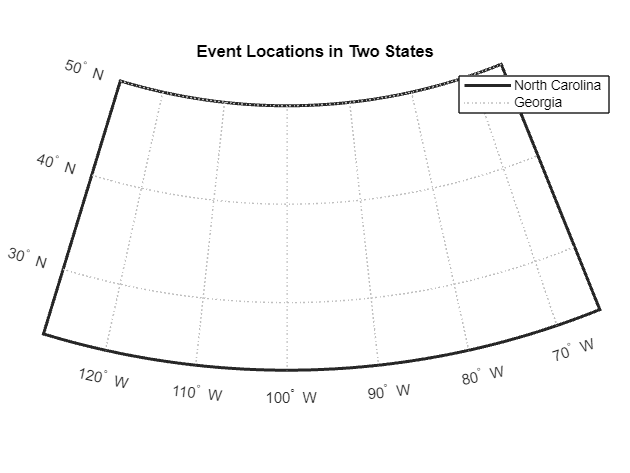

% Filter data for the two states
state1_events = events(strcmp(events.State, 'North Carolina'), :);
state2_events = events(strcmp(events.State, 'Georgia'), :);

% Create a new figure with a map of the United States
figure;
usamap('conus');

% Plot event locations for State 1
geoshow(state1_events.Begin_Lat, state1_events.Begin_Lon, 'DisplayType', 'point', 'Marker', 'o', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'b');

% Plot event locations for State 2
geoshow(state2_events.Begin_Lat, state2_events.Begin_Lon, 'DisplayType', 'point', 'Marker', 's', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r');

% Customize the map
xlabel('Longitude');
ylabel('Latitude');
title('Event Locations in Two States');
legend('North Carolina', 'Georgia');
grid on;